# Send Inputs to MATLAB Function from Command Line of Raspberry Pi

This example shows you how to deploy a MATLAB® function that accepts inputs from command line of Raspberry Pi® using MATLAB Support Package for Raspberry Pi Hardware. In this example, a MATLAB function for adding two numbers is used for deployment.

When you generate code for adding numbers the Raspberry Pi support package builds the executable on the hardware. You can then provide inputs to the executable as command line arguments. The executable adds the numbers and displays the output on the Raspberry Pi Linux® terminal.

**Note : **This example is applicable to the installed MATLAB Support Package for Raspberry Pi Hardware.

## Required Hardware

- Raspberry Pi hardware

- USB cable

- Ethernet cable

- A monitor connected to the Raspberry Pi hardware and a HDMI cable (optional)

## Prerequisite

Configure the Raspberry Pi network using [Hardware Setup](docid:mlsupportpkg#bt7xwov-2.mw_ce00da2f-bde9-4f39-a69a-a9aaf014dbc0) screen. 

## **Step 1: Connect the Raspberry Pi Hardware**

**Tip**: Before you start this example, we recommend you to complete the [Getting Started with MATLAB Support Package for Raspberry Pi Hardware](docid:mlsupportpkg.example-raspi_gettingstarted) example.

Connect the micro end of the USB cable to the Raspberry Pi and the regular end of the USB cable to the computer. Wait until the PWR LED on the hardware starts blinking.

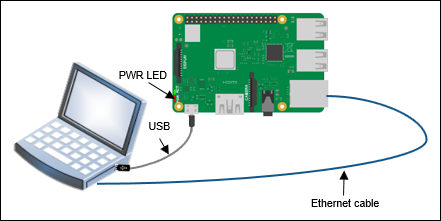

In the MATLAB Command Window, create a connection to the Raspberry Pi hardware.

r = raspi;

## Step 2: Open the Sum Function

In this example, the `simpleSum` function implements the logic for adding two numbers.

For more information on the function, enter this command in MATLAB Command Window.

type simpleSum

You can modify the function by using the `edit` command.

## Step 3: Generate C Code for Addition on Raspberry Pi

- Create a hardware configuration object by using the [targetHardware](docid:mlsupportpkg.mw_0826d141-e828-41a5-b465-cdf6268cb39a) function in the MATLAB Command Window. 

For Raspberry Pi with 32-bit OS, use:

For Raspberry Pi with 64-bit OS, use:

board = targetHardware('Raspberry Pi (64bit)');

Verify the `DeviceAddress`, `Username`, and `Password` properties listed in the output. If required, change the value of the properties by using the dot notation syntax. For example, to change the device address to `192.168.0.123`, enter, 

Set the `CoderConfig.GenCodeOnly` property of the board object to `true`. This enables the support package to generate and run the sum function code only on the host computer.

board.CoderConfig.GenCodeOnly = true;

Deploy the sum function on the hardware by using the [deploy](docid:mlsupportpkg.mw_a8a63ef5-1af4-460a-8515-2432dd5670b6) function. The `deploy` function initiates code generation of the `simpleSum` function. Once code generation is completed, MATLAB generates a code generation report. Use this report to debug the function for any errors and warnings in the generated code.

After successfully generating the code, update the `main.c` file to accept inputs from command line.

deploy(board,'simpleSum')

## **Step 4: Edit C Main and H Main Files to Accept Input from Command Line of Raspberry Pi**

This section explains how to modify the `main.c` and `main.h `file to accept inputs from command line of Raspberry Pi. Premodified `main.c` and `main.h `files are available for you to use. You can choose to use the premodified file or to update the file manually by using the steps in this section.

To use the premodified `main.c` and `main.h `files, enter these commands in the MATLAB Command Window.

copyfile('main.c',fullfile(pwd,'codegen','exe','simpleSum'))
copyfile('main.h',fullfile(pwd,'codegen','exe','simpleSum'))

To update the file manually, copy the generated `main.c` and `main.h` files to one level higher than the current level in the file hierarchy. Open the `main.c` file and update the file by adding code at the points labeled in this code.

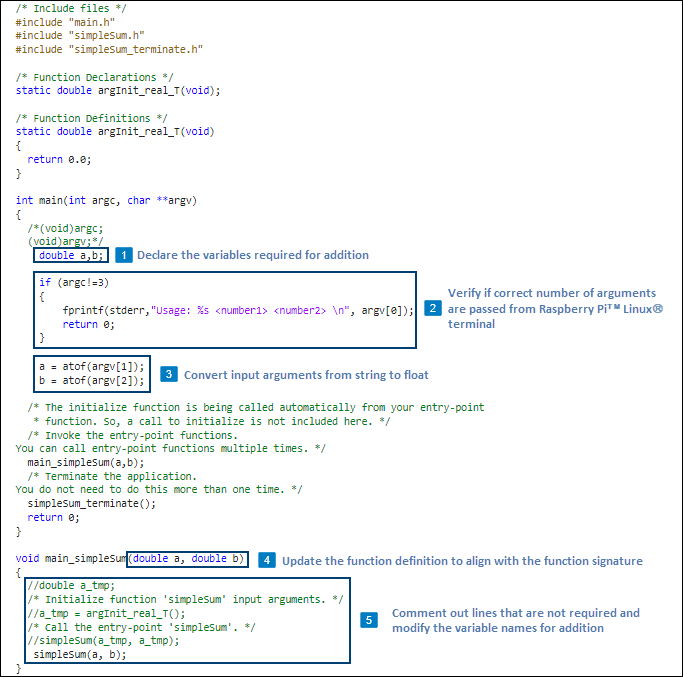

Also open the `main.h` file and update the file by adding code at the point labeled in this code.

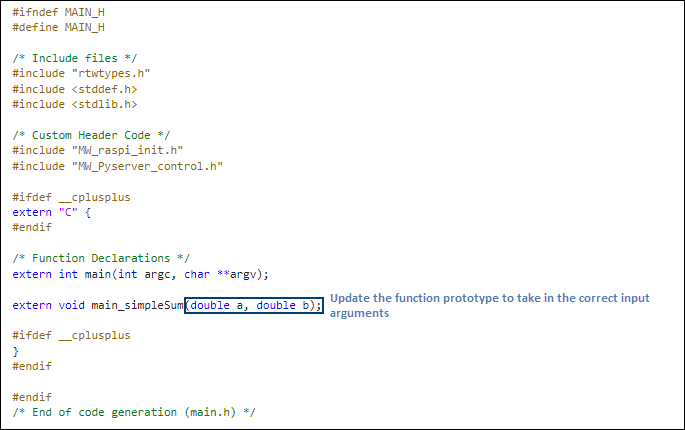

## **Step 5: Deploy the Function as a Standalone Executable on the Raspberry Pi**

To generate and deploy the code on the hardware, set the `CoderConfig.GenCodeOnly` property of the `board` object to `false` and then use the [deploy](docid:mlsupportpkg.mw_a8a63ef5-1af4-460a-8515-2432dd5670b6) function. Since the `deploy` function will overwrite the `main.c` file that you edited in the previous section, disable the creation of the file before deployment. 

board.CoderConfig.CustomSource = {fullfile(pwd,'codegen','exe','simpleSum','main.c')};
board.CoderConfig.CustomInclude = {fullfile(pwd,'codegen','exe','simpleSum','main.h')};
board.CoderConfig.GenerateExampleMain = 'DoNotGenerate';
board.CoderConfig.GenCodeOnly = false;

The `deploy` function initiates code generation of the `simpleSum` function.

After successfully generating the code, the support package loads the sum function as a standalone executable on the hardware. The location of the executable is displayed in the MATLAB Command Window. Note the location.

## **Step 6: Run the Executable Program to Add Numbers**

To open an SSH terminal with Raspberry Pi, use this command in the MATLAB Command Window. In the terminal, log in by entering the user name and password for the Raspberry Pi.

openShell(r)

Change the current directory to the directory where the executable was saved on the Raspberry Pi. This is the location that you noted in the previous step. 

Run the executable on the Raspberry Pi by providing inputs to the executable.

The executable adds the numbers and displays the output on the Linux terminal of the RaspberryPi.

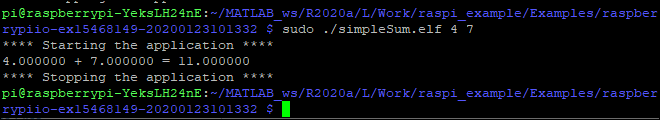

## See Also

- [Classify Static Image Using Deep Learning on Raspberry Pi](docid:mlsupportpkg.example-resnet50_ssh)

- [Identify Objects Within Video Using ResNet-50 on Raspberry Pi Hardware](docid:mlsupportpkg.example-resnet50_webcam)

*Copyright 2020 The MathWorks, Inc.*